%Fecha de actualización: 21/oct/2023
%V 0.0.1
%clc
%clear all

# Practica 001: Curso de MATLAB para ingeniería

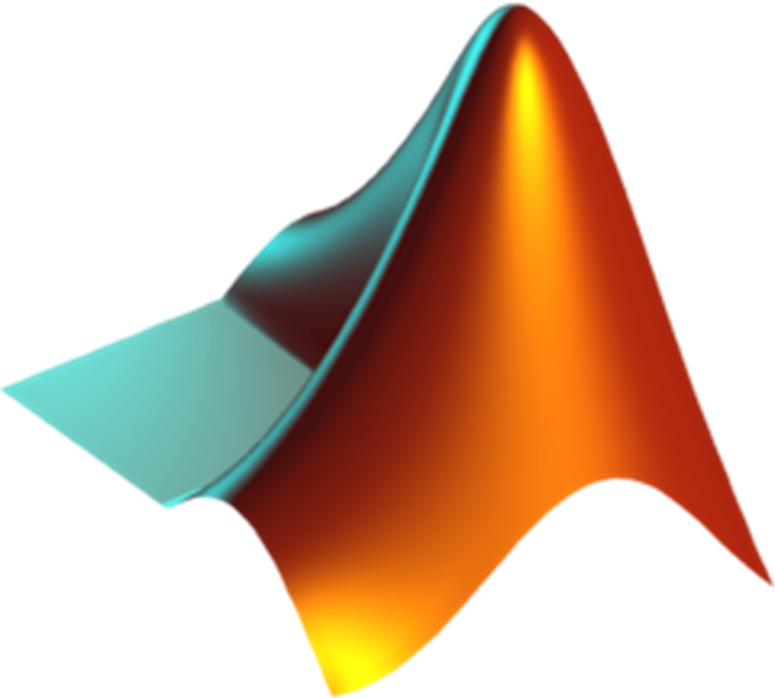

## Introducción

MATLAB (abreviatura de **MAT**rix**LAB**oratory, «laboratorio de matrices») es un sistema de cómputo numérico que ofrece un entorno de desarrollo integrado (IDE) con un lenguaje de programación propio (lenguaje M). Cuenta con un editor de código fuente, herramientas para la automatización de compilación local del software y un  depurador para probar otros programas y mostrar la ubicación de un error en el código original de forma gráfica.

## Tipos de datos en MATLAB

### Numéricos 

Clases numéricas en Matlab que incluyen valores con signo, sin signo, de simple precisión, de doble precisión, de punto flotante

%Para declarar comentarios puedes escribir el signo "%" al principio de una
%línea
%{
O puedes declarar bloques de comentarios con el conjunto de símbolos "%{" para abrir el bloque de 

a = 1.2346

comentarios y cerrar el bloque de comentarios "%}" con este otro conjunto

b = 3.1416

de símbolos
%}
%Para declarar un valor de tipo numérico, solo declara 

c = 4.3762

a=1.23456
b=3.1416132
%Además de esto, puedes lograr combinar las variables anteriores
%simplemente referenciando su valor
c=a+b
%Debes de tener cuidado al declarar las variables anteriores, ya que como
%todo lenguaje de programación tendras que mantener cierta lógica al momento de 
%escribir estas variables. Ademas de que existen palabras reservadas que no podrias 
% escribir tales como constantes de pi y e

### Cadenas de textos

%Las matrices de caracteres y las matrices de cadenas de caracteres 

d = "Hola mundo"

%permiten el almacenamiento de datos en forma de texto

e = 'Hola mundo'


d = "Hola mundo"
e = 'Hola mundo'

%Observa el resultado de las variables anteriores. En general el resultado
%en pantalla luce muy similar, pero al observar la forma en que MATLAB
%guarda los valores podras notar que el resultado es muy diferente

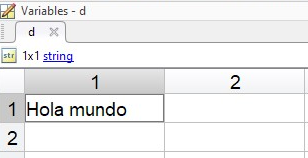

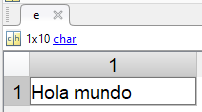

Ambos resultados almacenan el texto "Hola mundo", solo que el primero lo almacena como una cadena de caracteres, mientras que el segundo lo almacena como un texto. Esto implica que si se desea concatenar datos deberas tomar en cuenta la forma en que los datos estan siendo procesados y almacenados

%Si utilizas cadenas de caracteres es muy simple, solo agrega nuevas
%columnas a la variable de texto original, es decir
e = "Hola mundo,";
otraCadena = "estoy aprendiendo MATLAB";
resultado1 = [e, '', otraCadena];
disp(resultado1)

    "Hola mundo,"    ""    "estoy aprendiendo…"


%Por su parte, si estas utilizando texto, deberas de utilizar el
%comando strcat
d='Hola mundo,';
otraCadena = ' estoy aprendiendo mucho!';
resultado2 = strcat(e,otraCadena);
disp(resultado2)

Hola mundo, estoy aprendiendo mucho!


%Observa que el manejo de la información es distinta en uno u otro caso. En
%el primero deberás de indexar los resultados, mientras que en el segundo
%accedes solo a un indice compuesto de un orden específico

%El comando disp muestra el contenido de una variable
disp('Hola mundo')

Hola mundo



%El comando sprintf transforma el contenido de los datos en un vector de caracteres 
cadena=sprintf('Hola mundo 2.0')

cadena = 'Hola mundo 2.0'


%El comando fprintf muestra los datos contenidos y puede escribirlos
%directamente a un archivo de texto
fprintf('Hola mundo 3.0\n')

Hola mundo 3.0



%Muestra un comando de advertencia y apunta a la ultima funcion realizada
warning('Ten cuidao este es mi mundo')

%Muestra un comando de error
%error('Este es mi mundo')


%Puedes combinar entradas de datos con salidas de datos de la siguiente
%manera

a=1.23456;
b=3.1416132;
c=a+b;

%Utilizando la notacion disp
X=['1.- La suma de a=',num2str(a),' y b=',num2str(b),' es igual a',num2str(c)];
disp(X)

1.- La suma de a=1.2346 y b=3.1416 es igual a4.3762



%Utilizando la notacion sprintf
X2=sprintf('2.- La suma de a=%0.2f y b=%0.2f es igual a %0.2f',a,b,c)

X2 = '2.- La suma de a=1.23 y b=3.14 es igual a 4.38'


%Utilizando la notacion fprintf
fprintf('3.- La suma de "a"= %0.2f y "b"=%0.2f es igual a %0.2f\r',a,b,c)

3.- La suma de "a"= 1.23 y "b"=3.14 es igual a 4.38


### Operaciones boleanas

Las operaciones booleanas en MATLAB se trabajan como expresiones lógicas que dan como resultado valores lógicos (TRUE o FALSE). Por ejemplo observa las siguientes comandos

#### Operadores de comparación

- **Igualdad (==)** `Comprueba si dos valores son iguales.`

- **Desigualdad (~=):** `Comprueba si dos valores no son iguales.`

- **Mayor que (>):** `Comprueba si el valor de la izquierda es mayor que el de la derecha.`

- **Menor que (<):** `Comprueba si el valor de la izquierda es menor que el de la derecha.`

- **Mayor o igual que (>=):** `Comprueba si el valor de la izquierda es mayor o igual que el de la derecha.`

- **Menor o igual que (<=):** `Comprueba si el valor de la izquierda es menor o igual que el de la derecha.`

%Para realizar este ejercicio, compararemos dos datos de tipo numérico
a=5;
b=10;

%y evaluaremos el resultado de las siguientes operaciones lógicas
%   ┌---objeto en  ┌--Operación 
%   ↓   el           ↓    lógica
%   ↓   Workspace    ↓
%   ↓                ↓
%___|_____       ____|____
resultado1   =   (a == b)
resultado2 = (a < b)

#### Operadores lógicos

- **AND (**`&`** o **`&&`**): **`Devuelve True si ambas expresiones booleanas son True, de lo contrario, devuelve False.`

- **OR (**`|`** o **`||`**): **`Devuelve True si al menos una de las expresiones booleanas es True. Si ambas son False, devuelve False.`

- **NOT (**`~`**): **`Devuelve True si la expresión booleana es False y viceversa. Es un operador unario.`

%Se declaran dos datos de tipo logico
c = true;
d = false;

%Se evaluan los siguientes resultados 
%   ┌---objeto en  ┌--Operación 
%   ↓   el           ↓    lógica
%   ↓   Workspace    ↓
%   ↓                ↓
%___|______      ____|____
 resultado3   =   (c & d)   
resultado4 = (c | d)   
resultado5 = ~c        

#### Operadores de comparacion de elementos:

- Igualdad de elementos (`==`)

- Desigualdad de elementos (`~=`)

- Elementos de mayor valor que (`>`)

- Elementos de menor valor que (`<`)

- Elementos de mayor valor o equivalentes a  (`>=`)

- Elementos de menor valor o equivalentes a (`<=`)

%Primero declararemos dos elementos dentro del espacio de trabajo de MATLAB
vector1 = [1, 2, 3];
vector2 = [2, 2, 2];

%Y ahora compararemos mediante una operacion lógica el valor de cada uno de
%los elementos dentro del elemento principal, creando una matriz general
%lógica
%   ┌---Objeto en  ┌--Operación 
%   ↓   el           ↓    lógica
%   ↓   Workspace    ↓
%   ↓                ↓
%___|______    ______|____________
 resultado6 =  (vector1 == vector2)
%Analiza el resultado y observa que el unico valor que es identico en ambos
%elementos es el valor de 2

### Datos de tipo Fecha 

En Matlab, los datos de tipo fecha y hora se manejan utilizando la clase 'datetime'. Esta proporciona un formato completo y funcional que permite trabajar con fechas y horas 

%Creacion de los objetos 'datetime'
% Si desear crear un objeto que contenga la fecha y hora actual escribe el
% siguiente comando
fechaActual = datetime('now')

% Para escribir una fecha específica deberas indicar

% Objeto en el             ---Formato de entrada de datos---
%   workspace                aaaa ,  mm,  dd,  HH,  mm,  ss
%      ↓                       ↓     ↓    ↓    ↓    ↓    ↓
%______|________             __|__, _|_, _|_, _|_, _|_, _|_
 fechaEspecifica  = datetime( 2023,  10,  19,  12, 30 ,  0 )

% Crear una fecha a partir de una cadena de caracteres
fechaDesdeString = datetime('2023-10-19 12:30:00', 'InputFormat', 'yyyy-MM-dd HH:mm:ss')

#### Operaciones con datos de tipo Fecha:

Puedes realizar diversas operaciones con objetos de tipo 'datetime', como por ejemplo la suma y resta de valores para determinar la diferencia entre fechas, o verificar la relacion entre estas

% Calcular la diferencia entre dos fechas
diferencia = fechaEspecifica - fechaActual
% Verificar si una fecha es anterior a otra
esAnterior = fechaEspecifica < fechaActual
% Mostrar la fecha en formato de cadena de caracteres
cadenaFecha = datestr(fechaEspecifica, 'dd-mmm-yyyy HH:MM:SS')

### Arreglos de datos categoricos

En MATLAB, un arreglo de dato categórico es un tipo especial de arreglo de datos, el cual fue diseñado para trabajar con categorias de datos. Los datos categoricos son variables que toman un conjunto limitado y fijo de valores, generalmente denominados como etiquetas o categorias. Los arreglos categóricos proporcionan una forma eficiente de manejar y analizar datos en comparación con los arreglos numéricos o de celda

Para crear arreglos de datos categóricos, deberas de usar la funcion 'categorical', convirtiendo arreglos existentes a categóricos

categorias = {'Rojo', 'Verde', 'Azul'};
datos = categorical({'Rojo', 'Verde', 'Azul', 'Rojo'}, categorias);
disp(datos)

     Rojo      Verde      Azul      Rojo 


En este ejemplo, el objeto 'datos' es un arreglo categorico que contiene tres etiquetas llamadas 'Rojo', 'Verde' y 'Azul'. Puedes observar que el arreglo categórico solo almacena las categorias unicas y asigna un indice a cada valor, lo que resulta ser mas eficiente en terminos de almacenamineot y manipulacion de datos

Algunas de las operaciones que puedes realizar con arreglos categóricos incluyen:

#### Comparacion y filtrado

rojos = datos == 'Rojo'

rojos = 1×4 logical array
   1   0   0   1


#### Frecuencia de categorias

summary(datos)

     Rojo      Verde      Azul 
     2         1          1    
